# Developing a Monte Carlo Scheme

By Andrew John Buggee

## Let's try with a simple example first

#### The heart of the Monte Carlo method is to transform physical variables to a new random variable that has a uniform probability distribution

Let's look at a simple example. Lets define a simple probability distribution $P(x) = 2x$ and lets define $\xi$ as the uniformly distributed random variable, such that $P(\xi) = 1$. From the theorem of transforming variables of integration:


$$\int_{\xi_1}^{\xi_2} \, P(x) \frac{dx}{d\xi}\,d\xi = \int_{\xi_1}^{\xi_2} \, P(\xi)\,d\xi$$
 

For this to always be true, the integrands must be equal:


$$P(x) \frac{dx}{d\xi} = P(\xi) = 1$$


This is a first order differential equation for $x$ as a function of $\xi$. The solution should be able to recover the original PDF, $p(x)$. Using our example, our differential equation is:


$$2x \; \frac{dx}{d\xi} = 1$$


Which is a nice separable equation:


$$\int \, 2x\,dx = \int d\xi$$


This equation has the following solution:


$$x^2 = \xi + C$$
   

Where $C$ is a constant of integration. Subject to the boundary condition that $x = 0$ when $\xi = 0$, we find the solution is:


$$P(x(\xi)) = \sqrt{\xi}$$
 

Why do we use uniformly distributed random variables? We use the Monte Carlo method to estimate very complicated distributions. And we do this by sampling from an un-biased distribution, which by definition is a uniform distribution; all numbers are equally likely. After enough random samples from this unbiased distribution, we can estiamte the distribution of a much more complicated process.

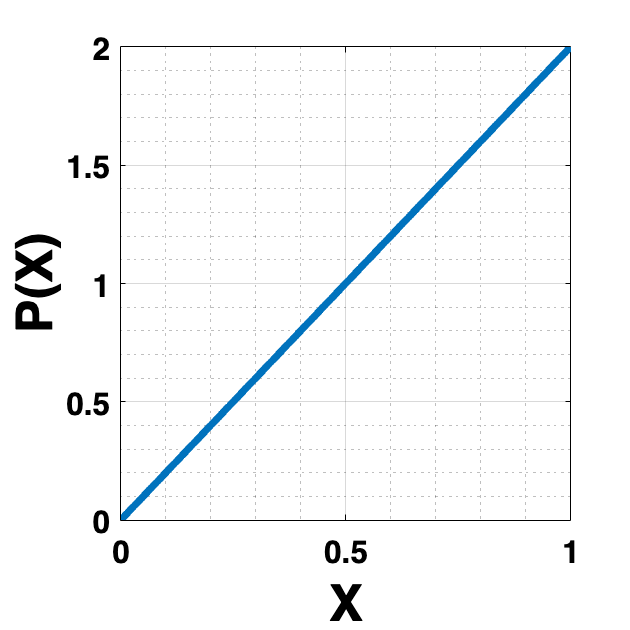

clear variables

% Start with a simple linear distribution
x_bounds = [0,1];                           % boundaries of x
p = @(x) 2*x;

% Let's plot the probability distribution p
x_samples = linspace(x_bounds(1), x_bounds(2), 200);
figure; plot(x_samples, p(x_samples))
grid on; grid minor
xlabel('X'); ylabel('P(X)')
set(gcf, 'Position',[0 0 350 350])

## Now lets try to recapture the above PDF



% Y is random variable such that P(Y) = 1
% x and y are related using the theorem for transforming variables of
% integration
x = @(Y) sqrt(Y);

% Lets generate N values of Y
% Y is a uniform probability density function
N_samples = 10;

% reset the random number generator
rng('default');
y = rand(N_samples,1);

% compute the corresponding values of x
x_draw = x(y);

% Let's solve for the probability density function

% define the number of bins in our distribution
N_bins = 10;

% define our new distribution
N_counts = zeros(1,N_bins);
% our bins are uniformly distributed
bin_width = (x_bounds(2) - x_bounds(1))/N_bins;

% assign each x to one of our bins
for nn=1:N_samples

    for bb = 1:N_bins

        if x_draw(nn)>=(x_bounds(1) + (bb-1)*bin_width) && x_draw(nn)<(x_bounds(1) + (bb)*bin_width)

            N_counts(bb) = N_counts(bb) + 1;

        end
    end
end


## Can we recover our original PDF?

Probability denisty functions are defined as the infintessimal change in $P(x)$ with respect to the infintessimal change in $x$. We can write this in a discrete way where $i$ represents a particular bin, and $N_i$ represents the number of counts in the $i^{th}$ bin:


$$P[x_i, x_{i+1}] = \frac{N[x_i, x_{i+1}]}{N (x_{i+1} - x_{i})}$$
 

By dividing the number of counts in each bin by the total number of counts we arrive at the probablity of a new observation occuring in each bin. Then by dividing by the bin width, we arrive at the probability density function, which is a differential quantity.

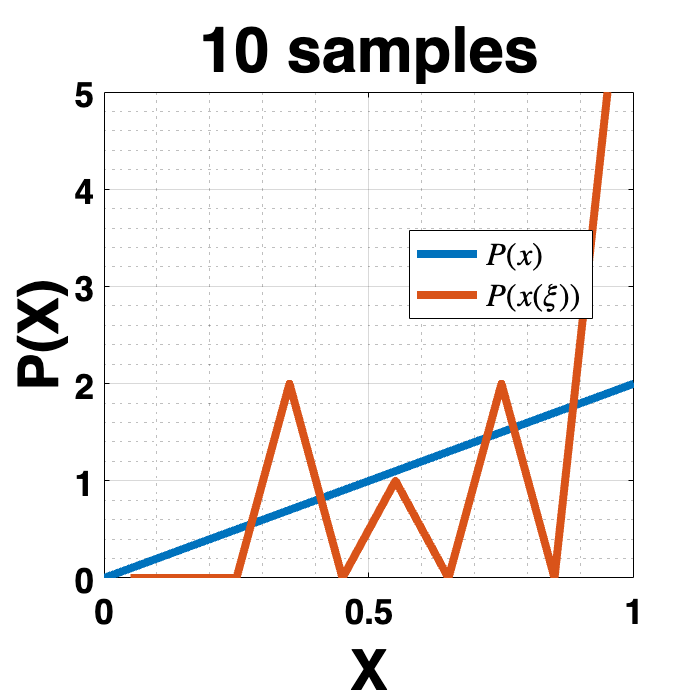


% Let's divide the number of counts in each bin by the total number of
% counts and the bin width to obtain the PDF

% Let's define the vector x to plot the PDF the center point of each bin
x_PDF = x_bounds(1)+(bin_width/2):bin_width:x_bounds(2)-(bin_width/2);

PDF = (N_counts./N_samples)./bin_width;

% Let's plot this PDF on top of our original PDF to see how we did

figure; plot(x_samples, p(x_samples))
hold on;
plot(x_PDF, PDF)
grid on; grid minor
xlabel('X'); ylabel('P(X)')
legend('$P(x)$','$P(x(\xi))$','interpreter','latex','Location','best')
title([num2str(N_samples), ' samples'])
set(gcf, 'Position',[0 0 350 350])

## How does this change as we increase the number of draws from the uniform distribution?

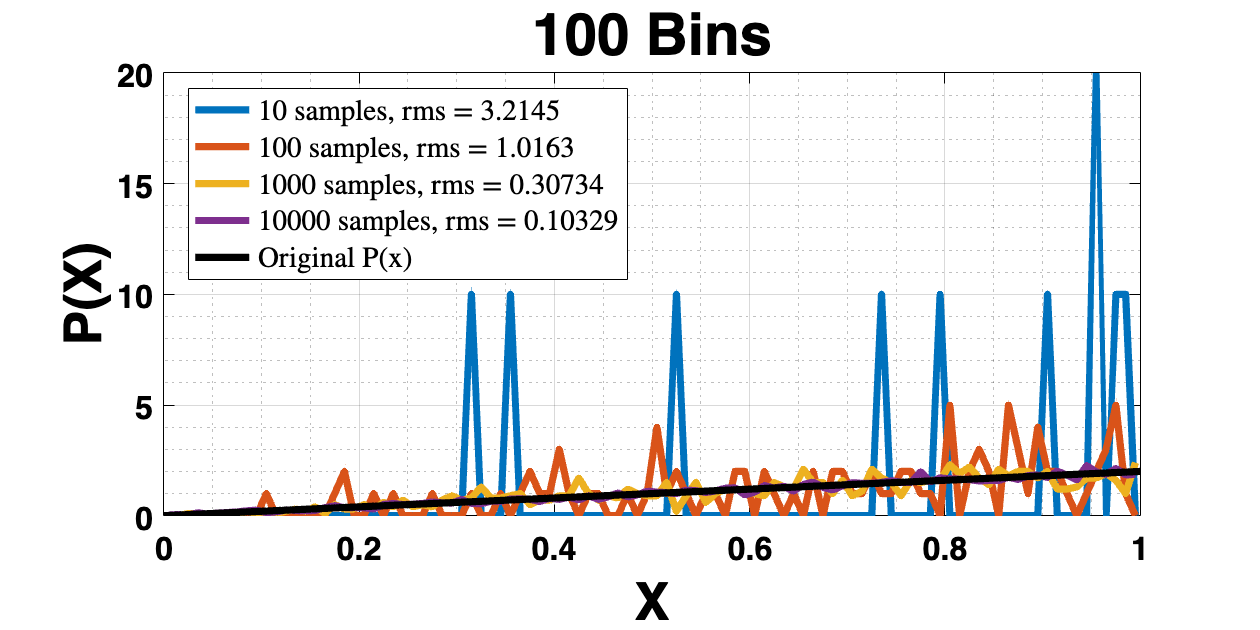

% Lets generate N values of Y
% Y is a uniform probability density function
N_samples = [10,100,1000, 10000];

% define the number of bins in our distribution
N_bins = 100;

% our bins are uniformly distributed
bin_width = (x_bounds(2) - x_bounds(1))/N_bins;

% Let's define the vector x to plot the PDF as the center point of each bin
x_PDF = x_bounds(1)+(bin_width/2):bin_width:x_bounds(2)-(bin_width/2);

% reset the random number generator
rng('default');

% define our new distribution
N_counts = zeros(length(N_samples),N_bins);

% Set the PDF to a zero matrix
PDF = zeros(length(N_samples),N_bins);

% Let's compute the RMS residual between the true PDF and our Monte Carlo
% estimate
rms_residual = zeros(1, length(N_samples));

% save lenged strings
legend_str = cell(1,length(N_samples)+1);


for dd = 1:length(N_samples)

    y = rand(N_samples(dd),1);

    % compute the corresponding values of x
    x_draw = x(y);


    % assign each x to one of our bins
    for nn=1:N_samples(dd)

        for bb = 1:N_bins

            if x_draw(nn)>=(x_bounds(1) + (bb-1)*bin_width) && x_draw(nn)<(x_bounds(1) + (bb)*bin_width)

                N_counts(dd,bb) = N_counts(dd,bb) + 1;

            end
        end
    end

    % Compute the PDF
    PDF(dd,:) = (N_counts(dd,:)./N_samples(dd))./bin_width;

    rms_residual(dd) = sqrt(1/N_bins * sum((p(x_PDF) - PDF(dd,:)).^2));

    legend_str{dd} = [num2str(N_samples(dd)),' samples, rms = ',num2str(rms_residual(dd))];

end

% add the original PDF to the legend string
legend_str{end} = 'Original P(x)';


% Plot the results versus the original PDF


figure; plot(x_PDF, PDF,'-')
hold on;
plot(x_samples, p(x_samples),'k')
grid on; grid minor
xlabel('X'); ylabel('P(X)')
title([num2str(N_bins), ' Bins'])
legend(legend_str,'interpreter','latex','Location','best')
set(gcf, 'Position',[0 0 750 450])

## What happens as we increase the number of bins, but fix the number of samples?

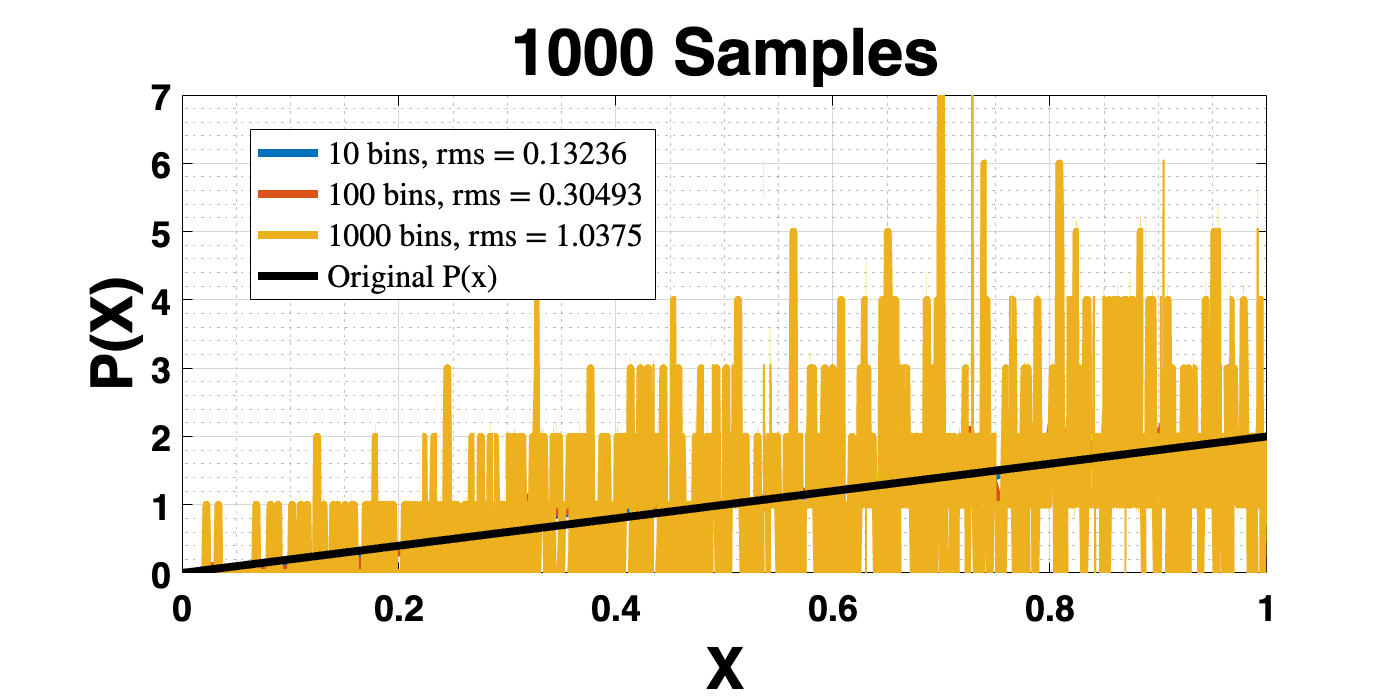

% Lets generate N values of Y
% Y is a uniform probability density function
N_samples = 1000;

% define the number of bins in our distribution
N_bins = [10, 100, 1000];

% our bins are uniformly distributed
bin_width = (x_bounds(2) - x_bounds(1))./N_bins;


% reset the random number generator
rng('default');

% The bin location vector increases in size with each iteration
x_PDF = cell(length(N_bins),1);

% Each bin size needs its own sized vector
N_counts = cell(length(N_bins),1);


% Set the PDF to a zero cell array, since it too changes size
PDF = cell(length(N_bins),1);

% Let's compute the RMS residual between the true PDF and our Monte Carlo
% estimate
rms_residual = zeros(1, length(N_samples));

% save lenged strings
legend_str = cell(1,length(N_bins)+1);

% We are drawing the same number of instances for each PDF


y = rand(N_samples,1);

% compute the corresponding values of x
x_draw = x(y);

for dd = 1:length(N_bins)

    % Let's define the vector x to plot the PDF the center point of each bin
    x_PDF{dd} = x_bounds(1)+(bin_width(dd)/2):bin_width(dd):x_bounds(2)-(bin_width(dd)/2);

    % Let's define this iterations Bin vector
    N_counts{dd} = zeros(1,N_bins(dd));


    % assign each x to one of our bins
    for nn=1:N_samples

        for bb = 1:N_bins(dd)

            if x_draw(nn)>=(x_bounds(1) + (bb-1)*bin_width(dd)) && x_draw(nn)<(x_bounds(1) + (bb)*bin_width(dd))

                N_counts{dd}(bb) = N_counts{dd}(bb) + 1;

            end
        end
    end

    % Compute the PDF
    PDF{dd} = (N_counts{dd}./N_samples)./bin_width(dd);

    rms_residual(dd) = sqrt(1/N_bins(dd) * sum((p(x_PDF{dd}) - PDF{dd}).^2));

    legend_str{dd} = [num2str(N_bins(dd)),' bins, rms = ',num2str(rms_residual(dd))];

end

% add the original PDF to the legend string
legend_str{end} = 'Original P(x)';


% Plot the results versus the original PDF


figure; 
for dd = 1:length(N_bins)
    plot(x_PDF{dd}, PDF{dd})
    hold on;
end

plot(x_samples, p(x_samples),'k')
grid on; grid minor
xlabel('X'); ylabel('P(X)')
title([num2str(N_samples), ' Samples'])
legend(legend_str,'interpreter','latex','Location','best')
set(gcf, 'Position',[0 0 700 350])

Interestingly our Monte Carlo solution of the original PDF started did poorly when we set the number of bins to equal the number of samples. Let's see how the RMS varies, for a fixed number of samples, as we vary the number of bins.

## How does the RMS change with changing number of bins for a fixed number of samples?

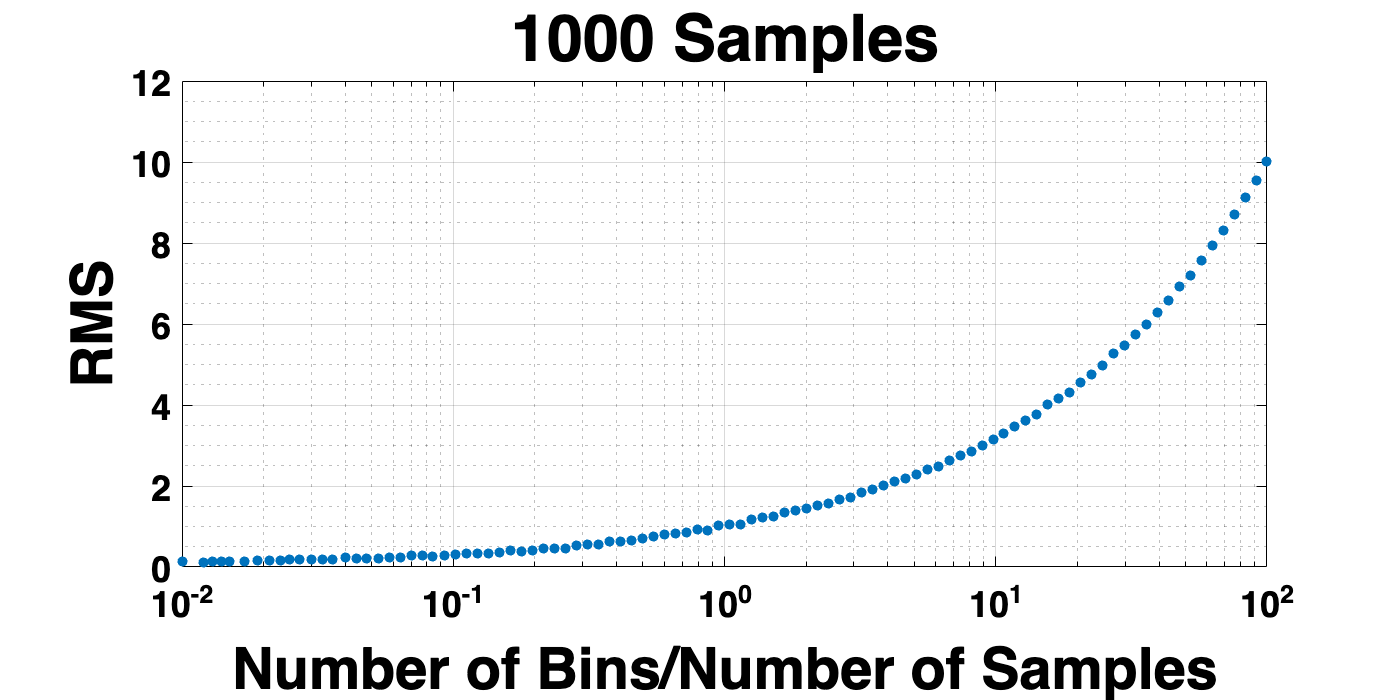

% Lets generate N values of Y
% Y is a uniform probability density function
N_samples = 1000;

% define the number of bins in our distribution
N_bins = floor(N_samples*logspace(-2,2,100));

% our bins are uniformly distributed
bin_width = (x_bounds(2) - x_bounds(1))./N_bins;


% reset the random number generator
rng('default');

% Let's compute the RMS residual between the true PDF and our Monte Carlo
% estimate
rms_residual = zeros(1, length(N_samples));


% We are drawing the same number of instances for each PDF


y = rand(N_samples,1);

% compute the corresponding values of x
x_draw = x(y);

for dd = 1:length(N_bins)
    
    clear x_PDF N_counts
    % Let's define the vector x to plot the PDF the center point of each bin
    x_PDF = x_bounds(1)+(bin_width(dd)/2):bin_width(dd):x_bounds(2)-(bin_width(dd)/2);

    % Let's define this iterations Bin vector
    N_counts = zeros(1,N_bins(dd));


    % assign each x to one of our bins
    for nn=1:N_samples

        for bb = 1:N_bins(dd)

            if x_draw(nn)>=(x_bounds(1) + (bb-1)*bin_width(dd)) && x_draw(nn)<(x_bounds(1) + (bb)*bin_width(dd))

                N_counts(bb) = N_counts(bb) + 1;

            end
        end
    end

    % Compute the PDF
    PDF = (N_counts./N_samples)./bin_width(dd);

    rms_residual(dd) = sqrt(1/N_bins(dd) * sum((p(x_PDF) - PDF).^2));

end


figure; semilogx(N_bins./N_samples, rms_residual,'.')
grid on; grid minor
xlabel('Number of Bins/Number of Samples'); ylabel('RMS')
title([num2str(N_samples), ' Samples'])
set(gcf, 'Position',[0 0 700 350])

This is werid and unexpected. The RMS difference between the original function and my estimate for the function using a Monte Carlo method increases with increasing bin number for a fixed number of samples. 

## Now let's look at a specfifc application of Monte Carlo to Radiative Transfer: Photon path length distribution

The probability of a photon traveling a physical distance $x$ is:


$$P(x) = \frac{1}{l} \exp(-\frac{x}{l})$$
 

Where $l$ is the mean free path. But we can also define the optical depth as $\tau = x/l$ and therefore the probability distribution of a photon traveling an optical path length $\tau$ before it is scattered or absorbed is :


$$P(\tau) = \exp(-\tau)$$
 

Once again, we want to find a relationship between our random variable, $\tau$ and a uniformly distributed random variable $\xi$. Using the theorem for the change of variables in integration:


$$\int\,P(\tau)\,\frac{d\tau}{d\xi}\,d\xi = \int\,P(\xi)\,d\xi$$


For this to be true, the integrands have to be equal:


$$P(\tau)\,\frac{d\tau}{d\xi} = P(\xi)$$


Which leads to a differential equation:


$$\int\,P(\tau)\,d\tau = \int\,P(\xi)\,d\xi$$


With $P(\xi) = 1$, our equation becomes:


$$\int\,\exp{(-\tau)}\,d\tau = \int\,d\xi$$



$$-\exp{(-\tau)} = \xi + C$$


Where $C$ is a constant of integration. Let's enforce the following boundary condition: $\tau = \infty$ when $\xi = 1$. Solve for $\tau$, we find the following relation:


$$\tau(\xi) = -\ln{(1 - \xi)}$$


Since $P(\xi) = 1$, $\xi \, \epsilon \, [0,1]$. Furthermore, we want $\tau$ to range from $\tau \, \epsilon \, [0,\infty)$. This is why the boundary conditions are the way they are.

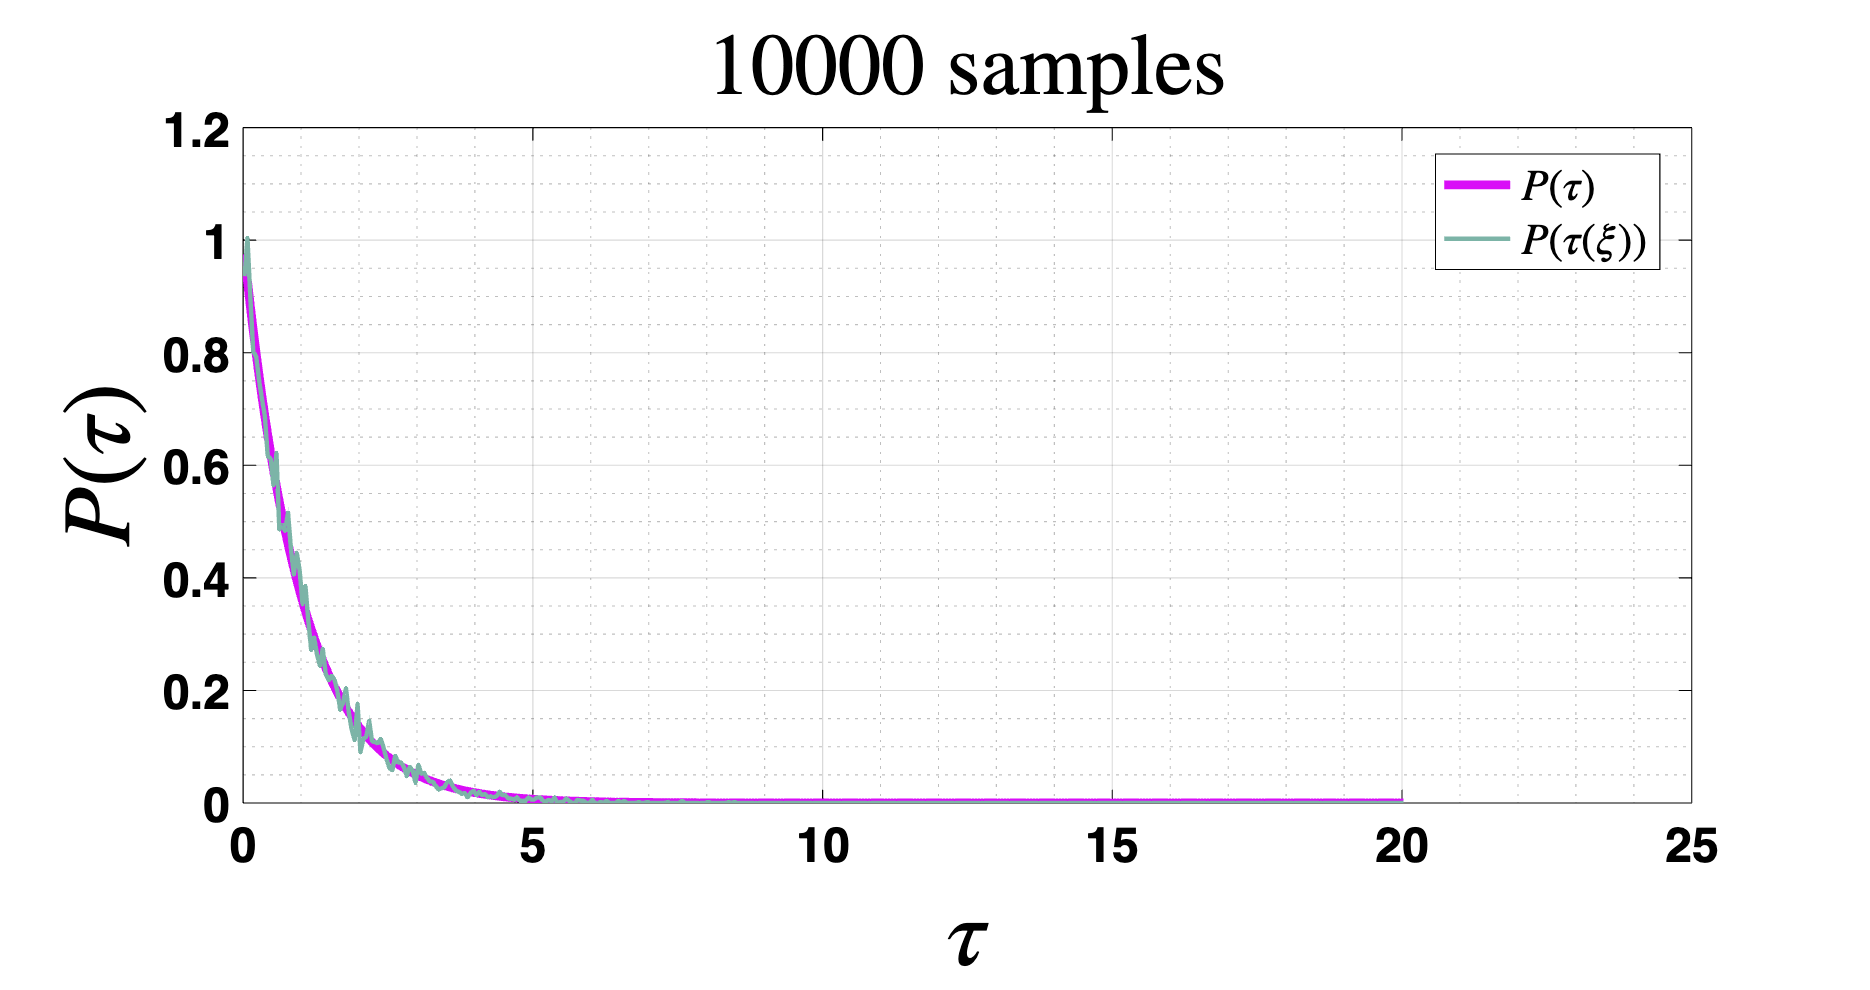

% define the original distribution

P_tau = @(tau) exp(-tau);

% Define the uniform distribution

N_samples = 10000;

% reset the random number generator
rng('default');


% define the relationship between x and tau

tau = @(x) -log(1 - x);


% We need to define the bins for the distribution we wish to compute. But
% the range is semi-infinite. So how do we treat this? We will allow the
% last bin to go to infinity. Usually, for N bins we have to define N+1
% edge points. In this case, we will only define N edge points and allow
% the last edge point to go to infinity

tau_boundaries = [0, inf];

% our bins are uniformly distributed
bin_width = 0.05; 

% define the bin edges
bin_edges = [tau_boundaries(1):bin_width:20, tau_boundaries(2)];

% define the number of bins

N_bins = length(bin_edges)-1;

% define our new distribution
N_counts = zeros(1,N_bins);

% assign each x to one of our bins
for nn=1:N_samples

    % draw a value from our uniform distribution
    x_draw = rand(1,1);
    tau_sample = tau(x_draw);

    for bb = 1:(N_bins+1)

        if tau_sample>=bin_edges(bb) && tau_sample<bin_edges(bb+1)

            N_counts(bb) = N_counts(bb) + 1;

        end
    end
end


% Let's divide the number of counts in each bin by the total number of
% counts and the bin width to obtain the PDF

% Let's define the vector x to plot the PDF the center point of each bin
tau_PDF = bin_edges(1)+(bin_width/2):bin_width:bin_edges(end-1)+(bin_width/2);

PDF = (N_counts./N_samples)./bin_width;



% Let's plot this PDF on top of our original PDF to see how we did


figure; plot(tau_PDF, P_tau(tau_PDF),"Color",mySavedColors(1,'fixed'))
hold on;
plot(tau_PDF, PDF,"Color",mySavedColors(2,'fixed'), 'LineWidth', 2)
grid on; grid minor
xlabel('$\tau$','Interpreter','latex');
ylabel('$P(\tau)$','Interpreter','latex')
legend('$P(\tau)$','$P(\tau(\xi))$','interpreter','latex','Location','best')
title([num2str(N_samples), ' samples'], 'Interpreter','latex')
set(gcf, 'Position',[0 0 850 450])

## Was our photon scattered or absorbed?

The probability a photon travels a distance $\tau$ before being scattered or absorbed is ploted above. But when an interaction does occur, how do we determine if it has been absorbed or scattered? The single scattering albedo $\tilde{\omega}$ is the probability that a photon scatters during an interaction. Therefore $1 - \tilde{\omega}$ is the probability of a photon being absorbed. How do we estimate this? Well, let's generate another random number from a uniform distribution. If the number is less than $\tilde{\omega}$ than we can say it was scattered. Why? $\tilde{\omega}$ defines the fraction of photons that are scattered. If $\tilde{\omega} = 0.7$ then 7 out of 10 interactions will, on average, result in a scattering event. Therefore any random number below $0.7$ is taken to be a scattering event because this is the representative portion of scattered events.

## In what direction did our photon scatter in?

If our photon scatters, it's life continues, but we must determine the direction it scatters into. The phase function is what defines the probability of a photon scattering in a particular direction. If we normalize the phase function so that the integral over all directions is equal to 1:


$$\int_{0}^{2\pi} \, \int_{0}^{\pi} \, p(\theta, \phi) \, \sin(\theta)\,d\theta \, d\phi = 1$$
 

Often the phase function is azimuthally symmetric, which means we can define the phase function as:


$$p(\theta, \phi) = \frac{p(\theta)}{2\pi}$$


 But remember that azimuthal symmetry is only true for spherically symmetric media with unpolaraized light. So what do we use for $p(\theta)$? Well if we are dealing with spheres, we can compute $p(\theta)$ using Mie theory. Of course these depend on the wavelength of incident light, the index of refraction of the sphere doing the scattering, and the size of the sphere. We could also use the approximation known as the Henyey-Greenstein function. This is simply a mathematical function which does a decent job of replicating the phase function as computed by Mie theory. 

*************************************************

******* Is this the best way to do this? ******

To do this using Mie theory, we need to compute the phase function, and fit some analytical function to it.  Then we can once again find an analytical expression that relates our uniform distribution to the more complex distribution.

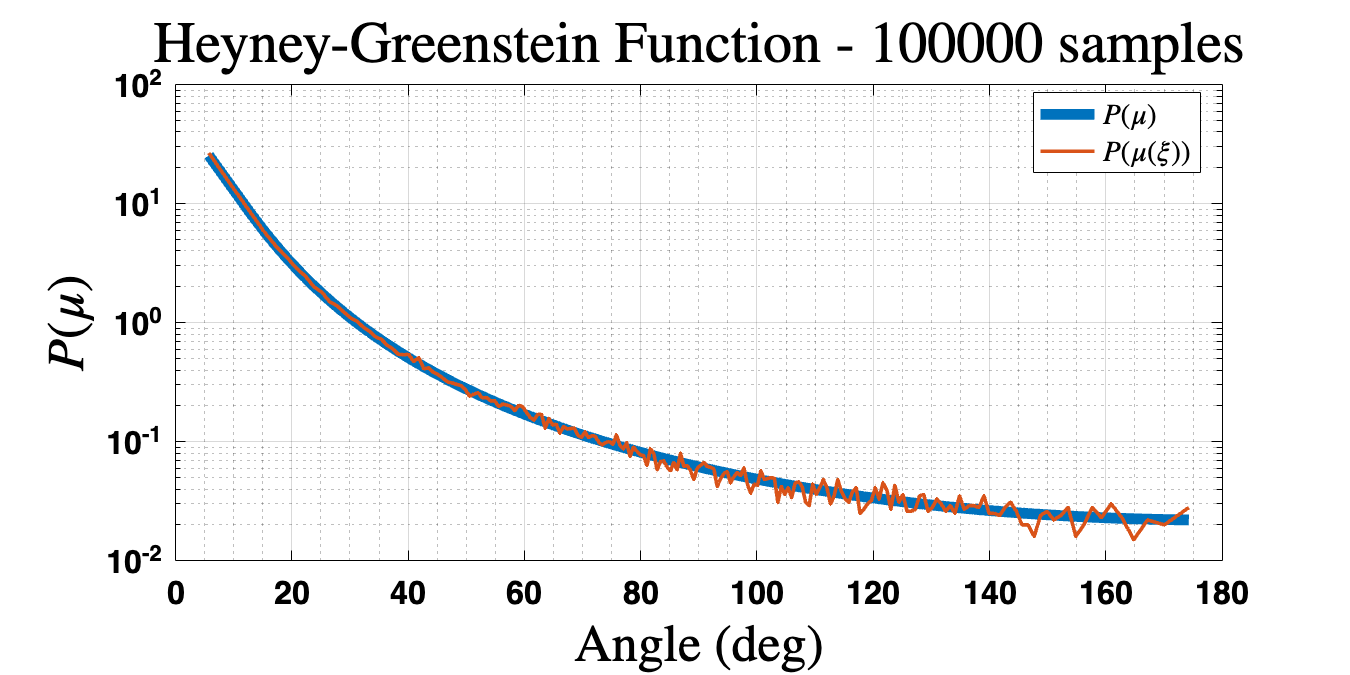

% Let's start with the Henyey-Greenstein function to estimate the
% scattering angle

% define the relationship between the Henyey-Greenstein function and the
% uniform distribution

P_hg = @(g, mu) (1 - g^2)/2 * 1./(1 + g^2 - 2*g*mu).^(3/2);

P_mu_x = @(g, x) 1/(2*g) * (1 + g^2 - ((1 - g^2)./(1 - g + 2*g*x)).^2);


% Define the number of samples
N_samples = 100000;

% Define the boundary conditions
% Let's convert from theta to cos(theta)

mu_boundaries = [-1, 1];

% our bins are uniformly distributed
bin_width = 0.01; 

% define the bin edges
bin_edges = mu_boundaries(1):bin_width:mu_boundaries(2);

% define the number of bins

N_bins = length(bin_edges)-1;


% Let's compute this for water
g_h2o = 0.85;

% define our new distribution
N_counts = zeros(1,N_bins);

% assign each x to one of our bins
for nn=1:N_samples

    % draw a value from our uniform distribution
    x_draw = rand(1,1);
    mu_sample = P_mu_x(g_h2o, x_draw);
    angle_sample = acosd(mu_sample);

    % Place the mu_sample and the angle sample in bins

    for bb = 1:(N_bins+1)

        if mu_sample>=bin_edges(bb) && mu_sample<bin_edges(bb+1)

            N_counts(bb) = N_counts(bb) + 1;

        end
    end
end


% Let's divide the number of counts in each bin by the total number of
% counts and the bin width to obtain the PDF

% Let's define the vector x to plot the PDF the center point of each bin
mu_PDF = bin_edges(1)+(bin_width/2):bin_width:bin_edges(end-1)+(bin_width/2);

PDF = (N_counts./N_samples)./bin_width;



% Let's plot this PDF on top of our original PDF to see how we did


figure; semilogy(acosd(mu_PDF), P_hg(g_h2o, mu_PDF), 'Linewidth',6)
hold on;
semilogy(acosd(mu_PDF), PDF, 'Linewidth',2)
grid on; grid minor
xlabel('Angle (deg)','Interpreter','latex');
ylabel('$P(\mu)$','Interpreter','latex')
legend('$P(\mu)$','$P(\mu(\xi))$','interpreter','latex','Location','best')
title(['Heyney-Greenstein Function - ',num2str(N_samples), ' samples'], 'Interpreter','latex')
set(gcf, 'Position',[0 0 750 375])

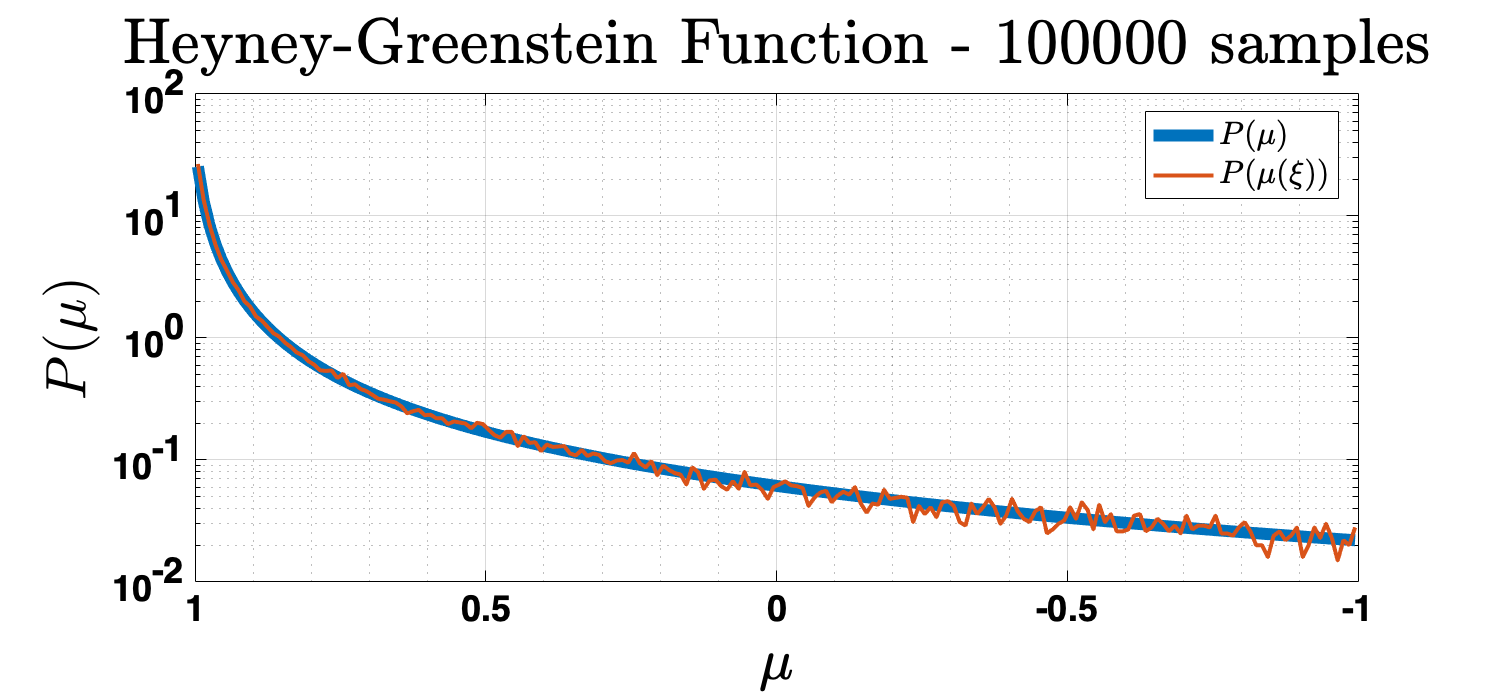

figure; semilogy(mu_PDF, P_hg(g_h2o, mu_PDF), 'Linewidth',6)
hold on;
semilogy(mu_PDF, PDF, 'Linewidth',2)
grid on; grid minor
xlabel('$\mu$','Interpreter','latex');
ylabel('$P(\mu)$','Interpreter','latex')
legend('$P(\mu)$','$P(\mu(\xi))$','interpreter','latex','Location','best')
title(['Heyney-Greenstein Function - ',num2str(N_samples), ' samples'], 'Interpreter','latex')
set(gca, 'XDir','reverse')
set(gcf, 'Position',[0 0 750 350])